## Naïve Bayes Analysis part 2

Analysis & Hyperparameter Search on the dataset here uses the standardised dataset with fewer features. 

Naive Bayes classification is performed using boostrapping, which is recomended for large datasets: the training and testing times are shortest..

Several metrics are calculated for the multiclass naive Bayes classifier: 

- precision, recall, accuracy[1] 

- F1 [2]. 

Training and testing of the training dataset is performed using MATlab's fitcnb and predict functionality [3]. All the kernel smoothing algorithms covered in the MATlab documentation [3] are evaluated.

### This section clears the workspace, loads the dataset

The dataset used is the standardised dataset, the features previously identified as not useful are removed.

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
%[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
%X = table2array(X);
%Y = table2array(Y);
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1



## Run Hyperparameter Search

Find start of error range

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalQuickHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesKernalNormalQuickSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 0.2000 
	Smoother Type: normal normal normal normal normal normal normal normal normal normal normal normal 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 815 entries out of 3200. 25.4688 pct
	Training loss: 0.24. Test Loss: 0.25
	Precision: 0.7466 Recall: 0.7586 Accuracy: 0.7453 F1: 0.7526
Test run HoldRunCount: 1 of 1,Width: 0.1800 
	Smoother Type: normal normal normal normal normal normal normal normal normal normal normal normal 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 423.0000

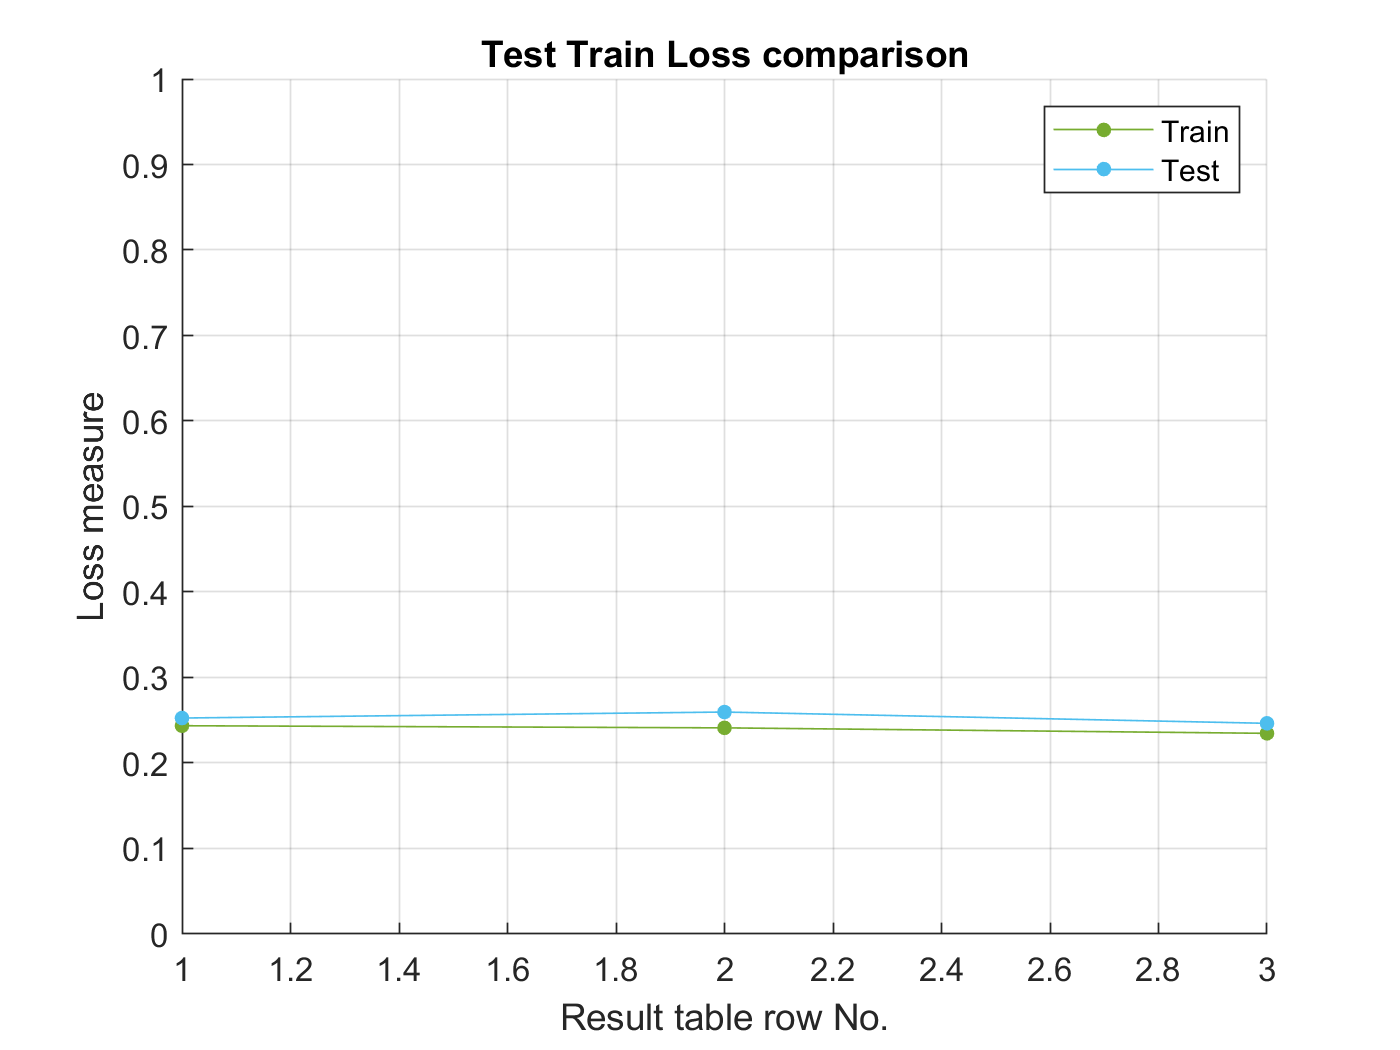

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

results.resultsTable

ans = 3×12 table
    distributionName    smootherType    Width    numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    _____    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}        {'normal'}      0.2             1                0.2436         0.2526         0.7453          0.7466        0.7586      0.7526       3200         163.06   
       {'kernel'}        {'n

### Using Default 'normal' Distribution Name

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getDefaultTestHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesDefaultSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: -1.0000 
	Smoother Type: N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A 
	DistName: 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 1098 entries out of 3200. 34.3125 pct
	Training loss: 0.34. Test Loss: 0.34
	Precision: 0.6591 Recall: 0.6690 Accuracy: 0.6569 F1: 0.6640
Test run HoldRunCount: 1 of 2,Width: -1.0000 
	Smoother Type: N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A N/A 
	DistName: 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 'normal' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 24.3750

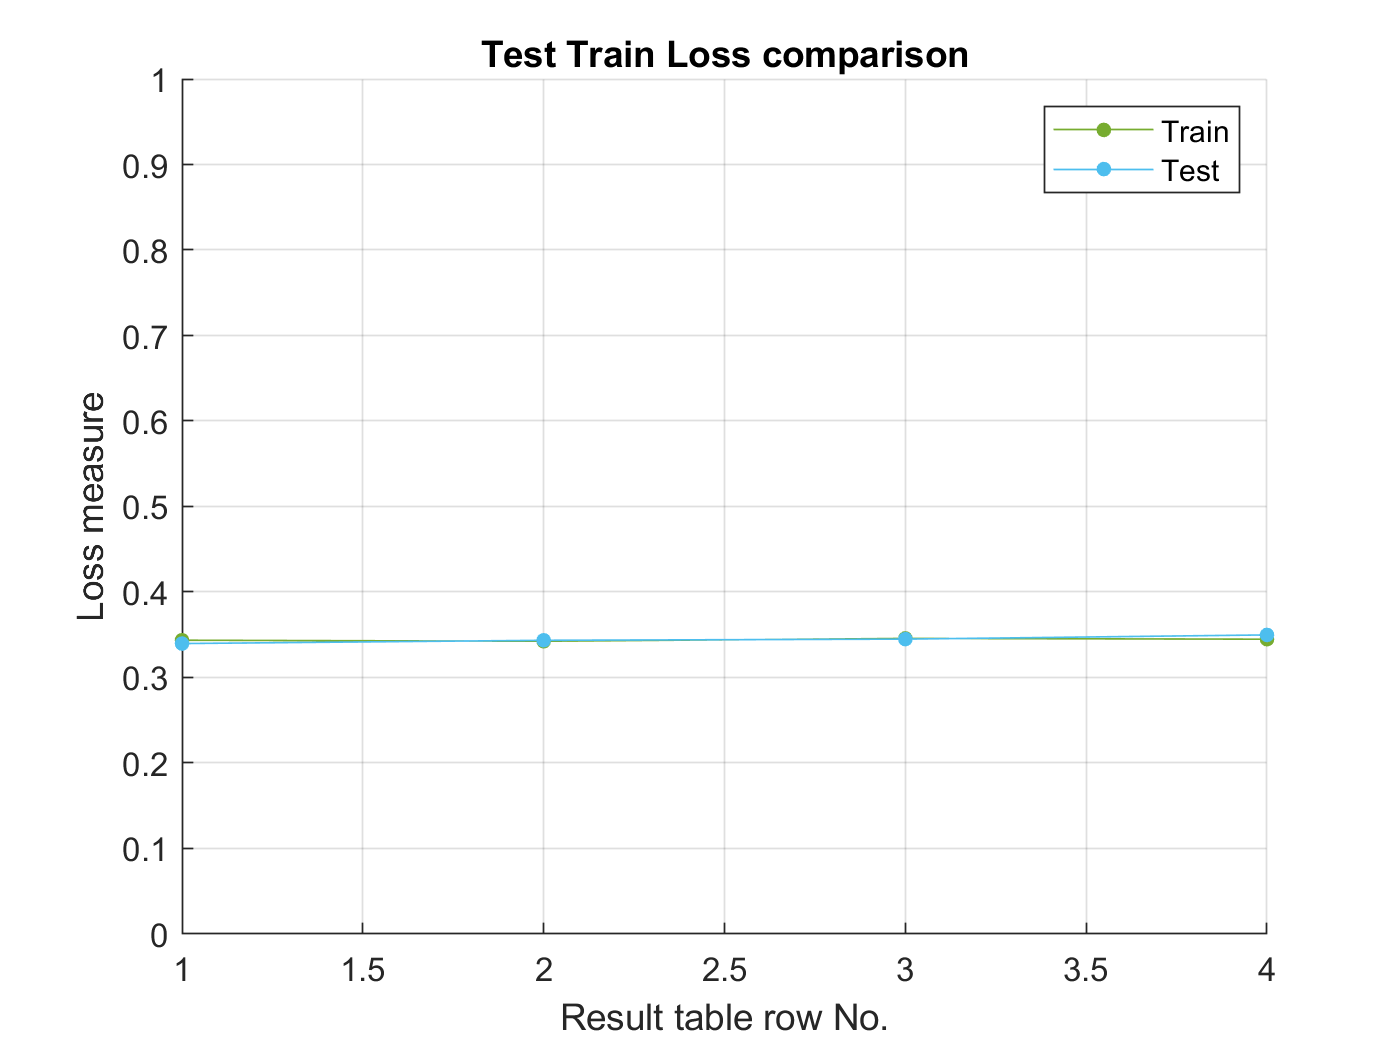

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

results.resultsTable

ans = 4×12 table
    distributionName    smootherType    Width    numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    _____    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'normal'}        {'unused'}      -1               1               0.3436         0.3397         0.6569          0.6591         0.669       0.664       3200         1.4688   
       {'normal'}        {'u

### Kernel Distribution Names (uses normal distribution for each feature)

#### Triangle Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernelTriangleSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesTriangleSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 0.1300 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 768 entries out of 3200. 24.0000 pct
	Training loss: 0.23. Test Loss: 0.24
	Precision: 0.7615 Recall: 0.7729 Accuracy: 0.7600 F1: 0.7672
Test run HoldRunCount: 1 of 2,Width: 0.1300 
	Smoother Type: triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle triangle 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2526.8125

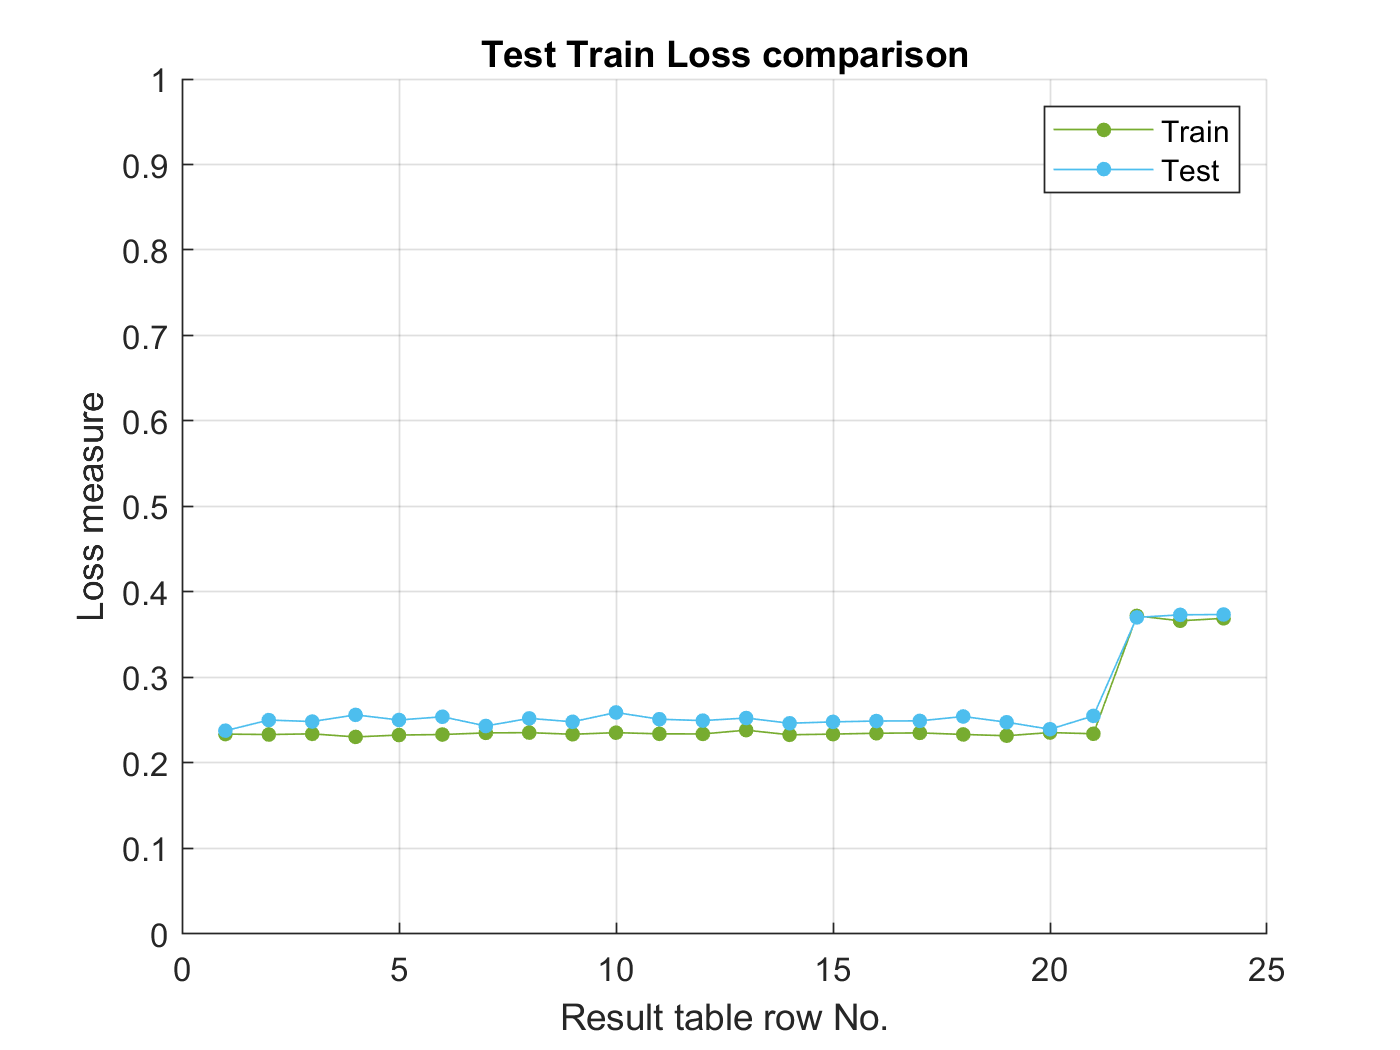

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

results.resultsTable

ans = 24×12 table
    distributionName    smootherType     Width      numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    ________    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}       {'triangle'}        0.13            1                0.2338         0.2378           0.76          0.7615        0.7729      0.7672       3200         40.359   
       {'kernel'} 

#### Normal Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesNormalSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 0.2000 
	Smoother Type: normal normal normal normal normal normal normal normal normal normal normal normal 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 815 entries out of 3200. 25.4688 pct
	Training loss: 0.24. Test Loss: 0.25
	Precision: 0.7466 Recall: 0.7586 Accuracy: 0.7453 F1: 0.7526
Test run HoldRunCount: 1 of 2,Width: 0.2000 
	Smoother Type: normal normal normal normal normal normal normal normal normal normal normal normal 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 5541.3281

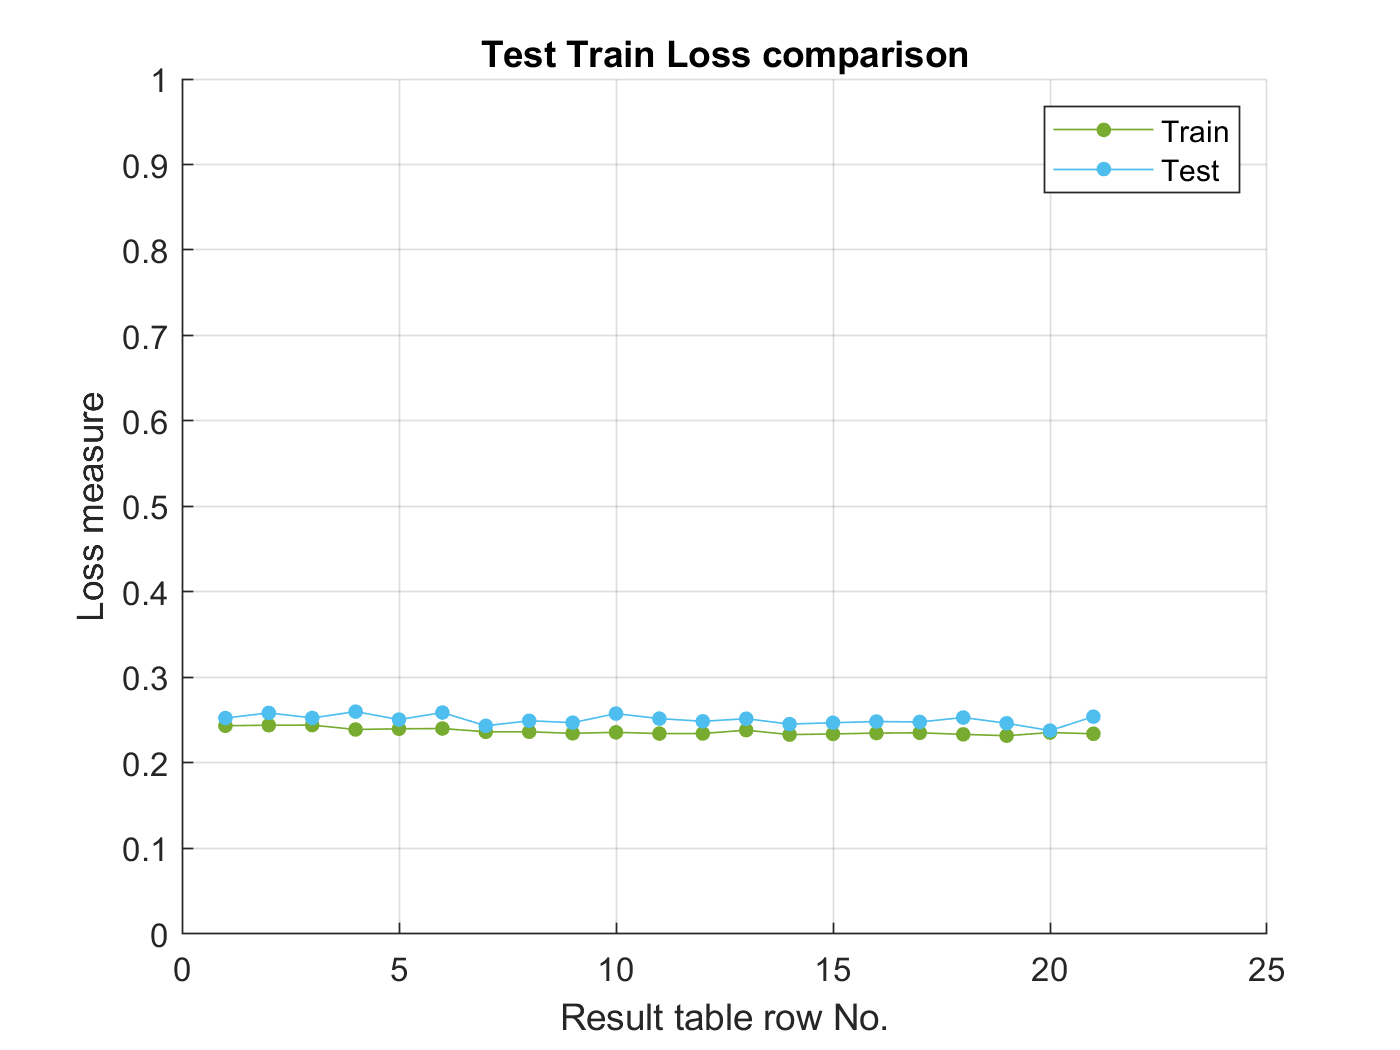

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

results.resultsTable

ans = 21×12 table
    distributionName    smootherType    Width    numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    _____    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}        {'normal'}      0.2             1                0.2436         0.2526         0.7453          0.7466        0.7586      0.7526       3200         165.38   
       {'kernel'}        {'

#### Epanechnikov Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalEpanechnikovSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesEpanechikovSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 0.2000 
	Smoother Type: epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 825 entries out of 3200. 25.7813 pct
	Training loss: 0.25. Test Loss: 0.26
	Precision: 0.7435 Recall: 0.7555 Accuracy: 0.7422 F1: 0.7494
Test run HoldRunCount: 1 of 2,Width: 0.2000 
	Smoother Type: epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov epanechnikov 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'k

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 1732.8594

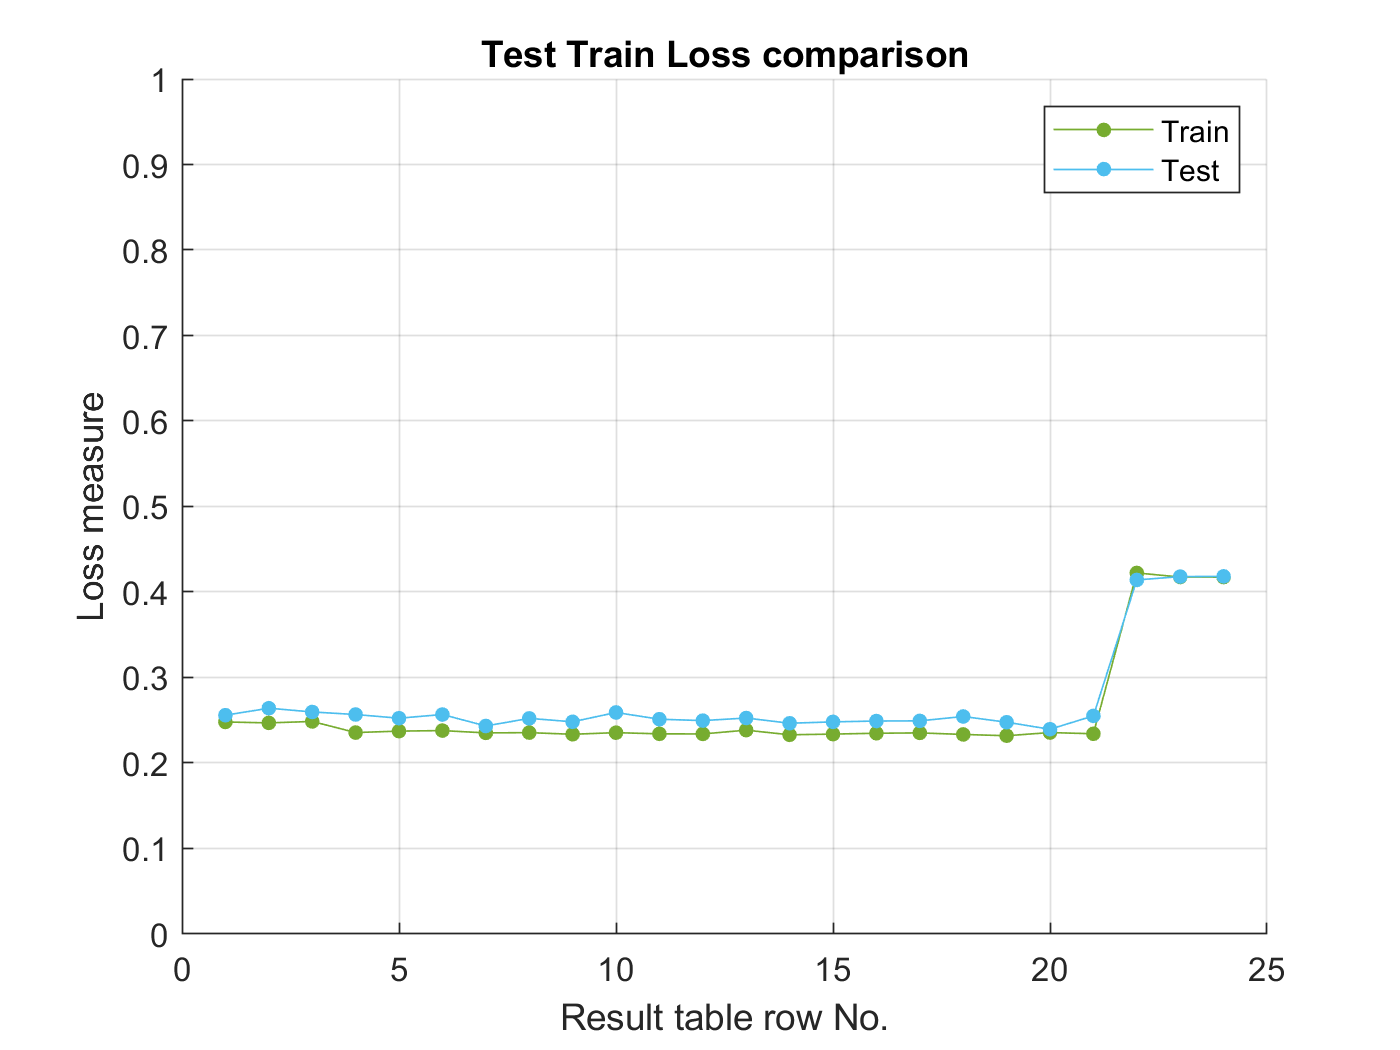

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

results.resultsTable

ans = 24×12 table
    distributionName      smootherType      Width    numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ________________    _____    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}       {'epanechnikov'}     0.2             1                 0.248         0.2559         0.7422          0.7435        0.7555      0.7494       3200         29.203   
       {'kernel

#### Box Smoother Type

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalBoxSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesBoxSmootherSearch.csv");

Starting decision tree analysis...
Test run HoldRunCount: 1 of 1,Width: 0.2000 
	Smoother Type: box box box box box box box box box box box box 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0.0404 0.0378 0.0366 0.0367 
Misclassified 768 entries out of 3200. 24.0000 pct
	Training loss: 0.23. Test Loss: 0.24
	Precision: 0.7615 Recall: 0.7729 Accuracy: 0.7600 F1: 0.7672
Test run HoldRunCount: 1 of 2,Width: 0.2000 
	Smoother Type: box box box box box box box box box box box box 
	DistName: 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 'kernel' 
	prior: 0.0413 0.0379 0.0399 0.0383 0.0393 0.0391 0.0396 0.0387 0.0382 0.0375 0.0381 0.0361 0.0381 0.0361 0.0384 0.0381 0.0384 0.0394 0.0386 0.0407 0.0393 0.0377 0

endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 1510.2031

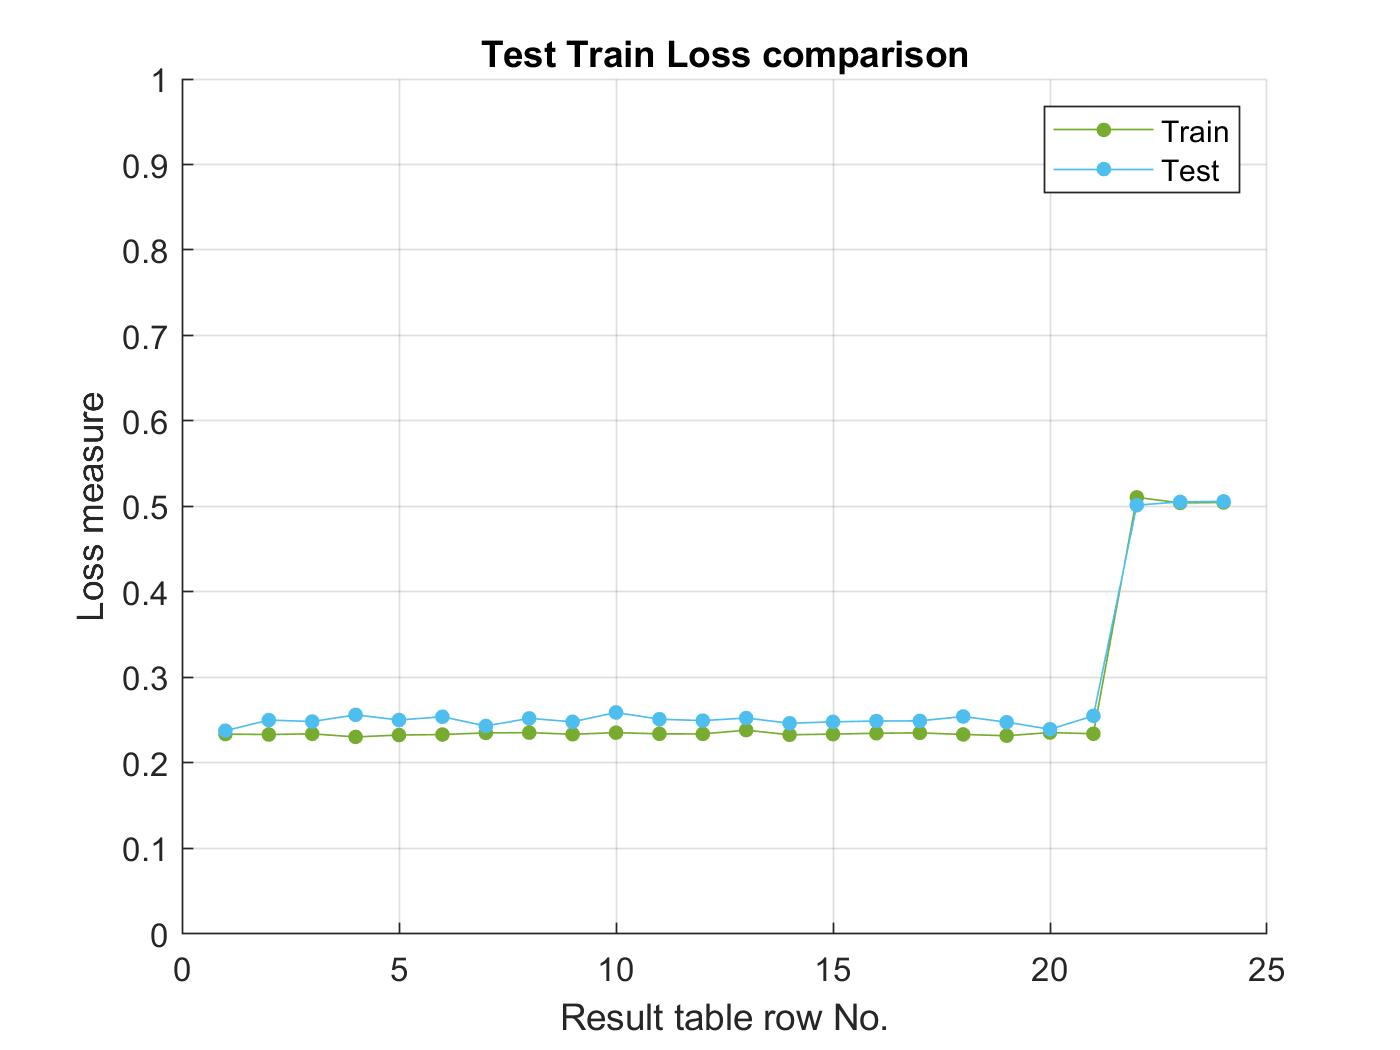

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

results.resultsTable

ans = 24×12 table
    distributionName    smootherType    Width    numberOfHoldOutRun    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    ________________    ____________    _____    __________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

       {'kernel'}         {'box'}        0.2             1                0.2338         0.2378           0.76          0.7615        0.7729      0.7672       3200         22.563   
       {'kernel'}         {

### References

[1] [Multi-Class Metrics Made Simple, Part I: Precision and Recall | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-i-precision-and-recall-9250280bddc2)

[2] [Multi-Class Metrics Made Simple, Part II: the F1-score | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-ii-the-f1-score-ebe8b2c2ca1)

[3] Train multiclass naive Bayes model, fitcnb. MATLAB documentation. [https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html](https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html)